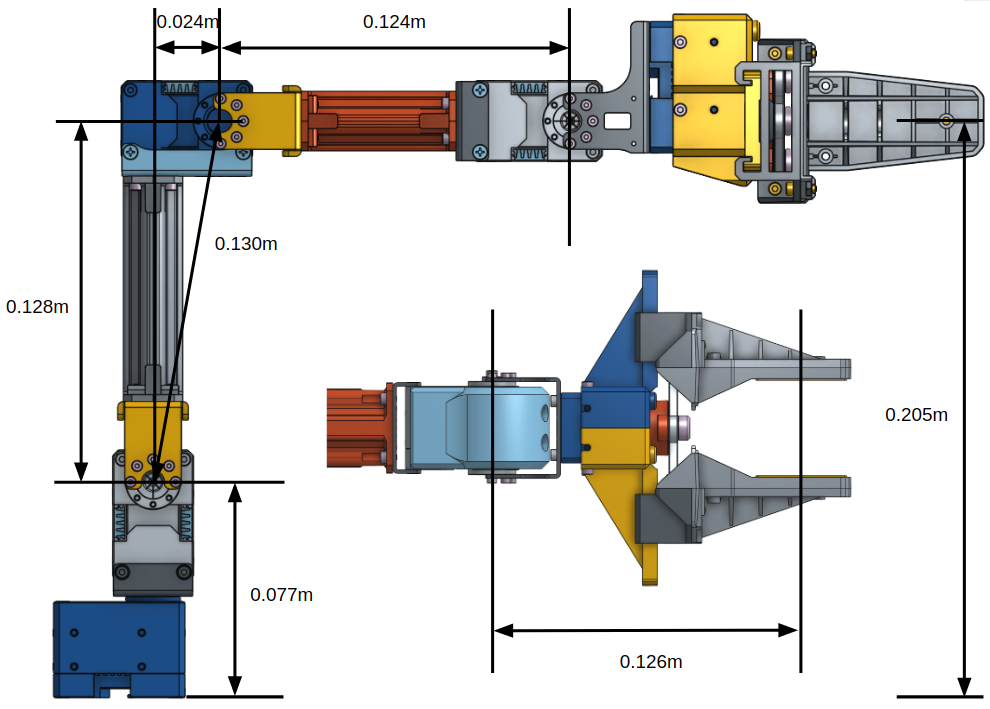

# Denavit-Heartenberg

clc;
clear all;

syms q1 q2 q3 q4

% crear el robot
R(1) = Link([0 0.077 0 pi/2 0]);
R(2) = Link([0 0 0.130 0 0]);
R(2).offset = 1.389282;
R(3) = Link([0 0 0.124 0 0]);
R(3).offset = -1.389282;
R(4) = Link([0 0 0.126 0 0]);

% unir eslabones y crear robot
robot_1 = SerialLink(R, "name", "RobotisX");
%robot_1.teach

# Cinemática Directa

% obtener cinemática directa por medio de funciones
R(1).A(q1);
R(2).A(q2);
R(3).A(q3);
R(4).A(q4);

% obtener cinemática directa de forma manual
dmxl_1 = trotz(q1) * transl([0, 0, 0.077]) * transl([0, 0, 0]) * trotx(pi/2)

$$dmxl\_1 = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & 0 & \sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & 0 & -\cos\left(q_{1}\right) & 0\\ 0 & 1 & 0 & \frac{77}{1000}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

dmxl_2 = trotz(q2) * transl([0, 0, 0]) * transl([0.130, 0, 0]) * trotx(0) 

$$dmxl\_2 = \left(\begin{array}{cccc} \cos\left(q_{2}\right) & -\sin\left(q_{2}\right) & 0 & \frac{13\,\cos\left(q_{2}\right)}{100}\\ \sin\left(q_{2}\right) & \cos\left(q_{2}\right) & 0 & \frac{13\,\sin\left(q_{2}\right)}{100}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

dmxl_3 = trotz(q3) * transl([0, 0, 0]) * transl([0.124, 0, 0]) * trotx(0) 

$$dmxl\_3 = \left(\begin{array}{cccc} \cos\left(q_{3}\right) & -\sin\left(q_{3}\right) & 0 & \frac{31\,\cos\left(q_{3}\right)}{250}\\ \sin\left(q_{3}\right) & \cos\left(q_{3}\right) & 0 & \frac{31\,\sin\left(q_{3}\right)}{250}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

dmxl_4 = trotz(q4) * transl([0, 0, 0]) * transl([0.126, 0, 0]) * trotx(0)

$$dmxl\_4 = \left(\begin{array}{cccc} \cos\left(q_{4}\right) & -\sin\left(q_{4}\right) & 0 & \frac{63\,\cos\left(q_{4}\right)}{500}\\ \sin\left(q_{4}\right) & \cos\left(q_{4}\right) & 0 & \frac{63\,\sin\left(q_{4}\right)}{500}\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$



% todo el robot
q = [q1, q2, q3, q4];
cinematica_directa = robot_1.fkine(q);
T = robot_1.fkine([0 0 0 0]);
cinematica_directa = simplify(cinematica_directa);

# Cinemática Inversa

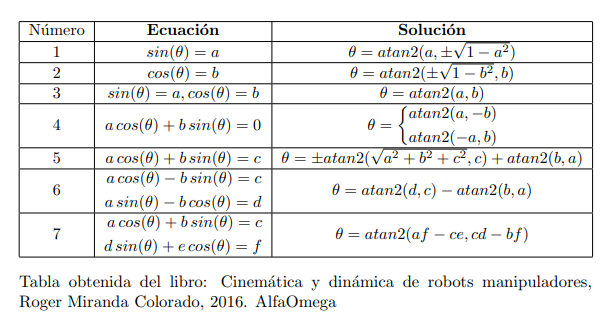

syms nx ny nz ox oy oz ax ay az px py pz

% punto a evaluar
coords = [0.2735, 0, 0.2049];
px = coords(1);
py = coords(2);
pz = coords(3);
ax = 0;
ay = -1;
az = 0;

% crear matriz NOAP 
noap_ = [nx ox ax px; ny oy ay py; nz oz az pz; 0 0 0 1];

%% --------------------------------- PASO 1 ---------------------------------

% encontrar la matriz que solo dependa de q1, ya que no tenemos ningun otro valor
p1_izq = inv(dmxl_1) * noap_;
p1_der = dmxl_2 * dmxl_3 * dmxl_4;
p1_izq = simplify(p1_izq);
p1_der = simplify(p1_der);

% definir primera ecuacion
ec_1 = p1_izq == p1_der;

% tomaremos las coordenadas: (3,4)
punto_1 = ec_1(3,4);
a_1 = -py;
b_1 = px;
% solo tiene 1 solucion
sol_1 = [atan2(a_1, -b_1), atan2(-a_1, b_1)]

sol_1 =    -3.1416         0


%% --------------------------------- PASO 2 ---------------------------------

% encontrar la matriz que dependa de q1 y q2
p2_izq = inv(dmxl_2) * inv(dmxl_1) * noap_;
p2_der = dmxl_3 * dmxl_4;
p2_izq = simplify(p2_izq);
p2_der = simplify(p2_der);

% definir segunda ecuacion
ec_2 = p2_izq == p2_der;

% tomaremos las coordenadas:
punto_2 = ec_2(2,3);

% evaluar con q1 para obtener q2
eval_2 = [az * cos(q2) - ax * sin(q2), % para q1 = 0
          az * cos(q2) - ax * sin(-q2)]; % para q1 = -pi;
% evaluado sale az*cos(q2) - ax*sin(q2) = 0
a_2 = az;
b_2 = -ax;
sol_2 = [atan2(a_2, -b_2), atan2(-a_2, b_2), atan2(a_2, -b_2), atan2(-a_2, b_2)]

sol_2 =      0     0     0     0


%% --------------------------------- PASO 3 ---------------------------------

% encontrar la matriz que dependa de q1, q2 y q3
p3_izq = inv(dmxl_3) * inv(dmxl_2) * inv(dmxl_1) * noap_;
p3_der = dmxl_4;
p3_izq = simplify(p3_izq);
p3_der = simplify(p3_der);

% definir tercera ecuacion
ec_3 = p3_izq == p3_der;

% tomaremos las coordenadas: (3,4)

punto_3 = simplify(ec_3(2,3));

% evaluar con q1 para obtener q3
eval_3 = [az*cos(0)*cos(q3) - az*sin(0)*sin(q3) - ax*cos(0)*cos(0)*sin(q3) - ax*cos(0)*cos(q3)*sin(0) - ay*cos(0)*sin(0)*sin(q3) - ay*cos(q3)*sin(0)*sin(0)]

$$eval\_3 = 0$$

% evaluar
a_3 = az;
b_3 = -ax;
sol_3 = [atan2(a_3, -b_3), atan2(-a_3, b_3)]

sol_3 =      0     0


% encontrar q4

% tomaremos las coordenadas: (1,4)
q1 = 0;
q2 = 1.389282;
q3 = -1.389282;

punto_4 = simplify(ec_3(1,4))

$$punto\_4 = 1300\,\cos\left(q_{3}\right)+1260\,\cos\left(q_{4}\right)+2735\,\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)+1240=1279\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)+1279\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)+2735\,\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)$$

punto_4 = eval(punto_4)

$$punto\_4 = 1260\,\cos\left(q_{4}\right)-\frac{41207902578965869}{35184372088832}=\frac{3135841280045495}{35184372088832}$$

punto_4 = simplify(punto_4)

$$punto\_4 = \cos\left(q_{4}\right)=\frac{3695311988250947}{3694359069327360}$$

% valor aproximado de b
3695311988250947/3694359069327360

ans = 1.0003

% se redondea a 1

% evaluar
b_4 = 1;
sol_4 = [atan2(sqrt(1-b_4^2), b_4), atan2(-sqrt(1-b_4^2), b_4)]

sol_4 =      0     0


La razón por la que se debe agregar el ángulo de offset al 0, es por la medida 0.130, dicha hipotenusa formada por los catetos 0.024 y 0.128. La razón por la que dan 0 q2 y q3 y la corrección ocurre en q4 es porque al poner 0.130 en la hipotenusa, "bloqueamos" esas dos articulaciones, haciendo que para que la medida sea cierta, no se muevan, hasta q4.

% ----------- COMPROBAR CINEMATICA INVERSA -----------
% crear el robot
R(1) = Link([0 0.077 0 pi/2 0]);
R(2) = Link([0 0 0.130 0 0]);
%R(2).offset = 1.389282;
R(3) = Link([0 0 0.124 0 0]);
%R(3).offset = -1.389282;
R(4) = Link([0 0 0.126 0 0]);

% unir eslabones y crear robot
robot_2 = SerialLink(R, "name", "RobotisX");

q1 = 0;
q2 = 0 + 1.389282;
q3 = 0 - 1.389282;
q4 = 0;
robot_2.plot([q1, q2, q3, q4])

% cinematica inversa con software
punto = T

 

punto = 
         1         0         0    0.2735
         0         0        -1         0
         0         1         0    0.2049
         0         0         0         1


robot_1.ikine(punto, "mask", [1 1 1 1 0 0])

ans =      0     0     0     0
